# Symbol Demodulation:  In-Class Exercises

## Computing SNR

In this example, we do a simple SNR calculation.  Consider a system with the parameters below.  For each path loss value, `PLTest(i), `find the SNR value,  SNR(i).  Plot `SNR` vs. `PLTest`.  

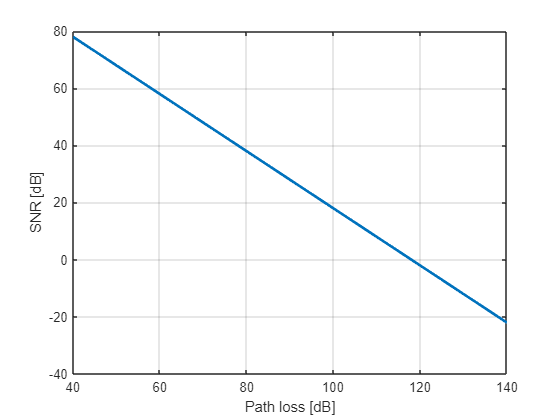

Ptx = 23;      % TX power in dBm
bw = 20e6;     % Bandwidth in MHz
PLTest = linspace(40,140,100)';  % Path loss values
NF = 6;   % RX noise figure in dB

% Boltzmann constant and temperature.  Note kT is in Watts not mW!
k = physconst('Boltzmann');
T = 290;  

% TODO:  Find and plot the RX SNR as a function of the PL.
%   SNR = ...
EkT = pow2db(k*T) + 30;  % Add 30 to convert from dBW to dBm.
Srx = Ptx - pow2db(bw) - PLTest;  % RX PSD
SNR = Srx - EkT - NF;  % RX SNR

plot(PLTest, SNR, 'LineWidth', 2);
grid on;
xlabel('Path loss [dB]');
ylabel('SNR [dB]');

## Simulating Noise in Discrete Symbols

In this exercise, we will show how to add noise to the QAM symbols.  First, create a set of random QAM modulated symbols with the following parameters.

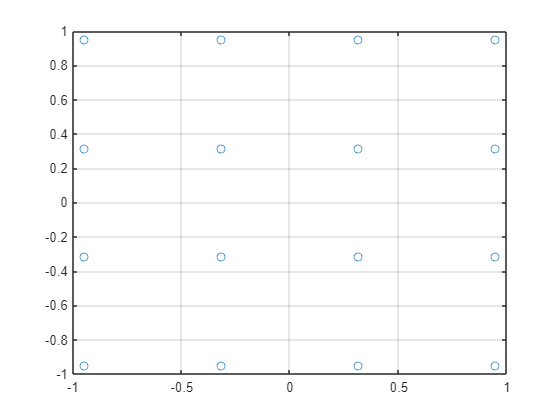

nsym = 1e4;    % number of symbols
bitsPerSym = 4;  % bits per symbol
nbits = bitsPerSym * nsym;

% TODO:  Create random bits and symbol
%   M = ...  % modulation order
%   b = ...  % random bits
%   s = qammod(..., 'UnitAveargePower', true)  % Random symbols.  
M = 2^bitsPerSym;  % modulation order
b = randi([0 1], nbits, 1);
s = qammod(b, M, 'InputType', 'bit', 'UnitAveragePower', true);

% TODO:  Plot the TX constellation
plot(real(s), imag(s), 'o');
grid on;

Create received symbols `r=s + w`.  where `w` is AWGN noise set to an SNR of `Es/N0` as shown.  PLot the received constellation.  Overlay the TX constellation.

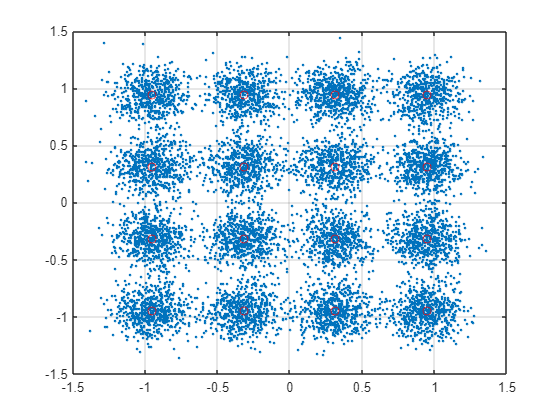

EsN0 = 15;  % Es/N0 in dB

% TODO:
%   w = ...
%   r = ...
%   plot(...)
w = db2mag(-EsN0)/sqrt(2)*(randn(nsym,1) + 1i*randn(nsym,1));
r = s + w;
plot(real(r), imag(r), '.');
hold on;
plot(real(s), imag(s), 'ro');
grid on;
hold off;

## Measuring the BER

MATLAB's commnuication toolbox has an excellent command, [qamdemod](https://www.mathworks.com/help/comm/ref/qamdemod.html), that can be used to demodulate the bits from the noisy symbols.  The syntax we will use is:

Note that you have to provide the average power since it is the reference level.  Use this command to get the estimated bits and find the BER.  At Es/N0 = 15 dB the BER should be ~ 0.45%.

% TODO:
%   bhat = qamdemod(r,M,'OutputType','bit', 'UnitAveragePower', true);
%   BER = ...
bhat = qamdemod(r,M,'OutputType','bit', 'UnitAveragePower', true);
ber = mean(bhat ~= b); 
disp(ber);

    0.0042



The above code measures the BER at a single SNR value.  Now, complete the following code to measure the BER as a function of the SNR, EsN0.

EsN0Test = linspace(5,15,11);  % SNR values to test
ntest = length(EsN0Test);
ber = zeros(ntest,1);

for i = 1:ntest
    EsN0 = EsN0Test(i);

    % TODO:  Create noisy symbols at the desired SNR
    %   w = ...
    %   r = ...
    w = db2mag(-EsN0)/sqrt(2)*(randn(nsym,1) + 1i*randn(nsym,1));
    r = s + w;

    % TODO:  Estimate the bits and BER
    %   bhat = ...
    %   ber(i) = ...

    bhat = qamdemod(r,M,'OutputType','bit', 'UnitAveragePower', true);
    ber(i) = mean(bhat ~= b);

    % TODO: Print EsN0 and BER
    fprintf(1,'EsN0 = %7.2f BER=%12.4e\n', EsN0, ber(i));

end

EsN0 =    5.00 BER=  1.6500e-01
EsN0 =    6.00 BER=  1.4005e-01
EsN0 =    7.00 BER=  1.1622e-01
EsN0 =    8.00 BER=  9.7225e-02
EsN0 =    9.00 BER=  8.0700e-02
EsN0 =   10.00 BER=  5.9200e-02
EsN0 =   11.00 BER=  4.3575e-02
EsN0 =   12.00 BER=  2.8150e-02
EsN0 =   13.00 BER=  1.6600e-02
EsN0 =   14.00 BER=  9.7750e-03
EsN0 =   15.00 BER=  3.8250e-03


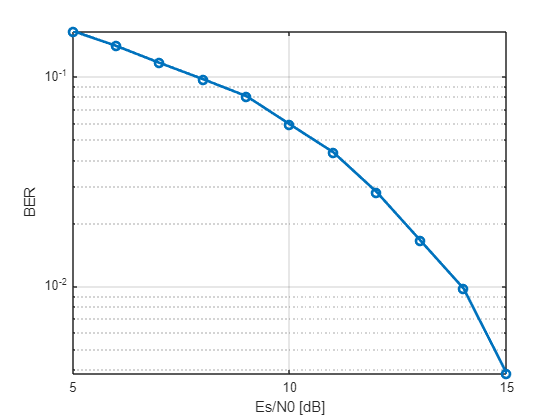


% TODO:  Plot ber vs. EsN0Test.  Use semilogy
semilogy(EsN0Test, ber, 'o-', 'LineWidth', 2);
grid on;
ylabel('BER');
xlabel('Es/N0 [dB]');

## Comparing to the Theoretical Value

We can compare the BER we just simulated to the theoretical values.  Proakis and other references show that, at high SNR, the symbol error rate is approximately:

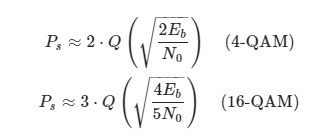

where `Eb/N0` is in linear scale.  With Gray coding, most symbol errors result in only one bit error per symbol.  Hence at high SNR, the  BER is approximately:

`     ber ~= ser / bitsPerSym`

Compute the theoretical BER for the Es/N0 values in `EsN0Theory`.  Plot `berTheory` vs. `EsN0Theory` on the same graph as the simualted values.  You should get a good match.

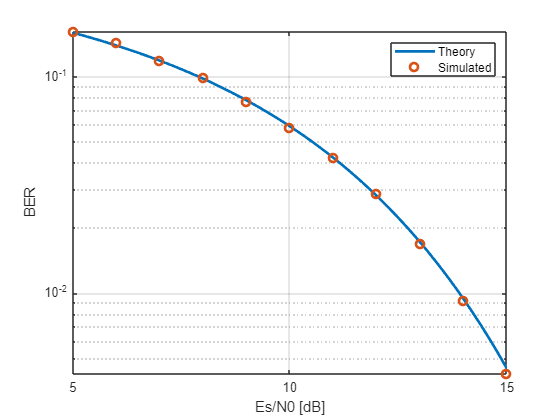

% Values of Es/N0 to compute the theoretical BER
EsN0Theory = linspace(5,15,100)';

% TODO:  Compute theoretical BER
%   berTheory
EbN0Lin = db2pow(EsN0Theory)/bitsPerSym;
serTheory = 3*qfunc(sqrt(0.8*EbN0Lin));
berTheory = serTheory/bitsPerSym;

% TODO:  Plot the BER vs. EsN0 for theory and simualted.  
% Label your plots
semilogy(EsN0Theory, berTheory, 'LineWidth', 2);
hold on;
semilogy(EsN0Test, ber, 'o', 'LineWidth', 2);
hold off;
grid on;
legend('Theory', 'Simulated');
xlabel('Es/N0 [dB]');
ylabel('BER');